clear
FFTSize = 4096;
hopsize = 1024;
overlapp = FFTSize -hopsize;

[signal,Fs] = audioread('AudioTest\BADSISTA_midi_BADSISTA_midi_bass_loop_pistao_01_130_Amin.wav');
signal = signal(:,1) % signal = toutes les lignes de la première colonne

signal =    -0.0003
   -0.0009
   -0.0013
   -0.0015
   -0.0016
   -0.0016
   -0.0015
   -0.0012
   -0.0007
   -0.0001




[FFTVector,frequencyBand,newTime] = spectrogram (signal,FFTSize,overlapp,FFTSize-1,Fs,'yaxis')

FFTVector =    0.6312 + 0.0000i   0.6098 + 0.0000i   0.0500 + 0.0000i  -0.4220 + 0.0000i   0.1301 + 0.0000i   0.4639 + 0.0000i  -0.2310 + 0.0000i  -0.2395 + 0.0000i   0.2374 + 0.0000i   0.0196 + 0.0000i  -0.2222 + 0.0000i  -0.3509 + 0.0000i   0.0984 + 0.0000i   0.1949 + 0.0000i   0.1213 + 0.0000i  -0.0631 + 0.0000i  -0.0912 + 0.0000i   0.5511 + 0.0000i   0.4960 + 0.0000i  -0.0819 + 0.0000i   0.6180 + 0.0000i   0.0569 + 0.0000i  -0.3611 + 0.0000i   0.2965 + 0.0000i  -0.3167 + 0.0000i  -0.2153 + 0.0000i   0.5142 + 0.0000i  -0.1902 + 0.0000i  -0.1670 + 0.0000i   0.4281 + 0.0000i   0.2655 + 0.0000i   0.2939 + 0.0000i   0.3798 + 0.0000i  -0.3029 + 0.0000i  -0.3459 + 0.0000i   0.0497 + 0.0000i  -0.0570 + 0.0000i   0.1861 + 0.0000i   0.4251 + 0.0000i   0.0819 + 0.0000i   0.0932 + 0.0000i   0.1350 + 0.0000i   0.0784 + 0.0000i  -0.2997 + 0.0000i   0.0050 + 0.0000i   0.2088 + 0.0000i   0.4343 + 0.0000i   0.0564 + 0.0000i  -0.0759 + 0.0000i  -0.1688 + 0.0000i
  -0.7285 + 0.0863i  -0.2750 - 0.3608

frequencyBand = 	1.0e+04 *

         0
    0.0012
    0.0023
    0.0035
    0.0047
    0.0059
    0.0070
    0.0082
    0.0094
    0.0105


newTime =     0.0427    0.0640    0.0853    0.1067    0.1280    0.1493    0.1707    0.1920    0.2133    0.2347    0.2560    0.2773    0.2987    0.3200    0.3413    0.3627    0.3840    0.4053    0.4267    0.4480    0.4693    0.4907    0.5120    0.5333    0.5547    0.5760    0.5973    0.6187    0.6400    0.6613    0.6827    0.7040    0.7253    0.7467    0.7680    0.7893    0.8107    0.8320    0.8533    0.8747    0.8960    0.9173    0.9387    0.9600    0.9813    1.0027    1.0240    1.0453    1.0667    1.0880



HFCLocal = zeros(1,size(FFTVector,2))

HFCLocal =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


HFCDiff = zeros(1,size(FFTVector,2))

HFCDiff =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


for i=1:size(FFTVector,2)
    for y=1:size(FFTVector,1)
        HFCLocal(1,i) = HFCLocal(1,i) + y* abs(FFTVector(y,i))*abs(FFTVector(y,i));
    end
end
HFCDiff(1,1) = abs(HFCLocal(1,1))

HFCDiff = 	1.0e+05 *

    2.1389         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


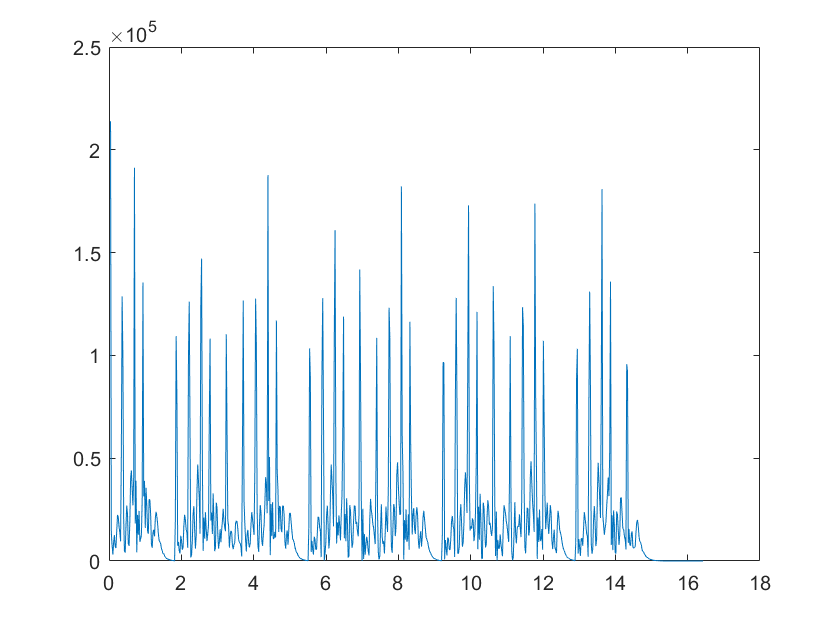

for i =2:size(HFCDiff,2)
    HFCDiff(1,i) = abs(HFCLocal(1,i)-HFCLocal(1,i-1));
end

plot(newTime,HFCDiff);




[pks,locs] = findpeaks(HFCDiff)

pks = 	1.0e+05 *

    0.1257    0.2232    1.2869    0.2699    0.4407    1.9126    0.3900    0.2241    0.2438    1.3546    0.3899    0.3561    0.3006    0.1519    0.2393    0.0360    1.0939    0.0928    0.1230    0.2246    1.2617    0.2664    0.4691    1.4706    0.2107    0.2373    1.0814    0.2350    0.3287    0.2842    0.1548    0.2541    1.1027    0.1468    0.1951    1.2672    0.1516    0.2376    1.2762    0.2726    0.4079    1.8770    0.5061    0.2771    0.2855    0.1424    1.1695    0.2677    0.2689    0.1487


locs =      6    10    16    22    28    32    34    36    38    43    45    47    51    57    60    70    86    89    92    97   103   109   114   119   122   124   130   132   134   138   143   147   151   157   164   173   179   184   189   195   202   205   207   209   211   214   216   220   225   230


median = std(HFCDiff)

median = 3.1441e+04

threshold = median + movmean(HFCDiff,20)

threshold = 	1.0e+04 *

    6.2424    6.1557    6.0444    5.9288    5.7980    5.9688    6.5965    6.9810    6.8851    6.7138    6.5556    5.5713    5.6383    5.7131    5.7403    5.7319    5.7631    5.9279    6.1170    6.2201    6.2440    6.3389    7.2115    7.2329    7.3803    7.1406    6.6092    6.1741    6.1904    6.2125    6.2460    6.2240    6.2362    6.8014    6.9158    7.0740    7.0607    7.0384    6.9538    6.8507    6.7817    6.7298    5.9220    5.9423    5.7881    5.7993    5.7564    5.7680    5.7061    5.7624





index=1

index = 1

for i =1 : size(pks,2)
    if pks(i) > threshold(locs(1,i))
        realpks(index) = pks(1,i);
        realLocs(index) = locs(1,i);
        index= index+1;
    end
end
realpks

realpks = 	1.0e+05 *

    1.2869    1.9126    1.3546    1.0939    1.2617    1.4706    1.0814    1.1027    1.2672    1.2762    1.8770    1.1695    1.0340    1.2788    1.6087    1.1889    1.4180    1.0852    1.2319    1.8222    1.1638    0.9664    1.2797    1.7299    1.2116    1.3372    1.0935    1.2342    1.7384    1.0714    1.0322    1.3102    1.8088    1.3591    0.9576


realLocs

realLocs =     16    32    43    86   103   119   130   151   173   189   205   216   259   276   292   303   324   346   362   378   389   432   449   465   476   497   519   535   551   562   606   622   638   649   670


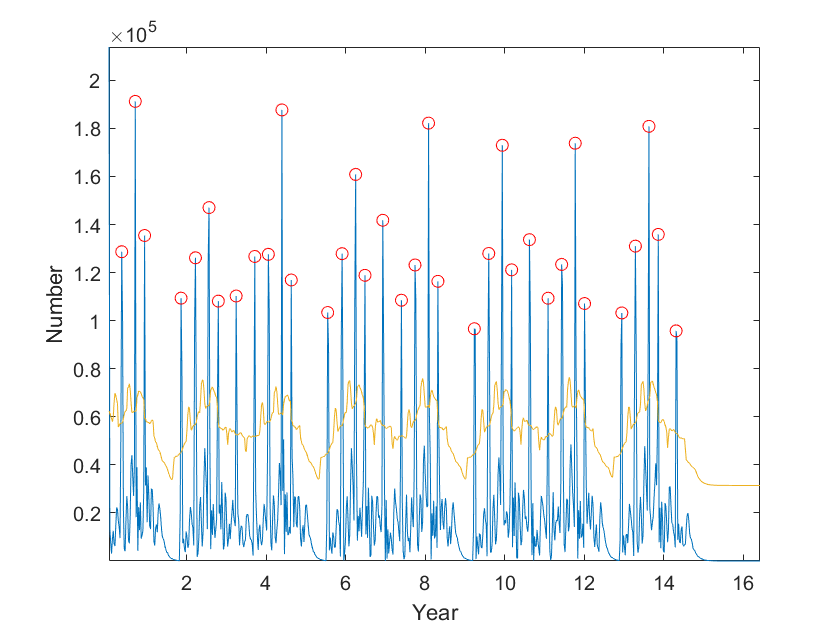

plot(newTime,HFCDiff,newTime(realLocs),realpks,'or')
xlabel('Year')
ylabel('Number')
axis tight
hold on;
plot(newTime,threshold)
hold off;



[x0,y0,iout,jout] = intersections(newTime,HFCDiff,newTime,threshold)

x0 =     0.0589
    0.3428
    0.3952
    0.6858
    0.7199
    0.9244
    0.9543
    1.8406
    1.8873
    2.1875


y0 = 	1.0e+04 *

    6.1766
    5.7397
    5.8497
    6.2428
    6.2331
    6.4617
    5.9368
    4.4914
    4.6441
    5.6642


iout =     1.7595
   15.0686
   17.5253
   31.1458
   32.7453
   42.3319
   43.7314
   85.2775
   87.4655
  101.5401


jout =     1.7595
   15.0686
   17.5253
   31.1458
   32.7453
   42.3319
   43.7314
   85.2775
   87.4655
  101.5401


realpks

realpks = 	1.0e+05 *

    1.2869    1.9126    1.3546    1.0939    1.2617    1.4706    1.0814    1.1027    1.2672    1.2762    1.8770    1.1695    1.0340    1.2788    1.6087    1.1889    1.4180    1.0852    1.2319    1.8222    1.1638    0.9664    1.2797    1.7299    1.2116    1.3372    1.0935    1.2342    1.7384    1.0714    1.0322    1.3102    1.8088    1.3591    0.9576


realLocs

realLocs =     16    32    43    86   103   119   130   151   173   189   205   216   259   276   292   303   324   346   362   378   389   432   449   465   476   497   519   535   551   562   606   622   638   649   670
